% Vin = 100 mkV
% L = 1.26 mkH
% R = 20 Ohm
% C = 0.567 pF = 0.567e-12 F
% a) f0 = 188 MHz
%    VC, IC -?
% b) Vout(f) - ?
% c) D_f = 6 MHz
%    kpod - ?
clear
digits(4)
% a)
% On Resonance frequancy
% Z=sqrt(R^2)=R = 20 Ohm
R=20

R = 20

Z=R

Z = 20

Vin=100e-6

Vin = 1.0000e-04

I0=Vin/Z

I0 = 5.0000e-06

%    5.0000e-06 A = 5 mkA
w=2*pi*188e6

w = 1.1812e+09

C=0.567e-12

C = 5.6700e-13

VC0a=I0*(1/(w*C))

VC0a = 0.0075

%   0.0075 V = 7.5 mV
VC0a/Vin

ans = 74.6533

% 74.6 times

% b)
% VC0=I0*XC=
syms V0 R w L C
VC0=(V0/sqrt(R^2+(w*L-1/(w*L))^2))*1/(w*C)

$$VC0 = \frac{V_{0}}{C\,w\,\sqrt{R^{2}+{\left(L\,w-\frac{1}{L\,w}\right)}^{2}}}$$

syms f f0 
VC0=V0/sqrt((2*pi*f*R*C)^2+(f^2/f0^2-1)^2)

$$VC0 = \frac{V_{0}}{\sqrt{{\left(\frac{f^{2}}{{f_{0}}^{2}}-1\right)}^{2}+4\,C^{2}\,R^{2}\,f^{2}\,\pi^{2}}}$$

% f0=1/(2*pi*sqrt(L*C))
% f01=vpa(subs(f0,[L C],[1.26e-6 0.567e-12]))
% 1.883e8 Hz = 188 MHz
VC01(f)=vpa(subs(VC0,[V0 R C f0],[100e-6 20 0.567e-12 188e6]))

$$VC01(f) = \frac{0.0001}{\sqrt{{\left(2.829\,10^{-17}\,f^{2}-1.0\right)}^{2}+5.077\,10^{-21}\,f^{2}}}$$

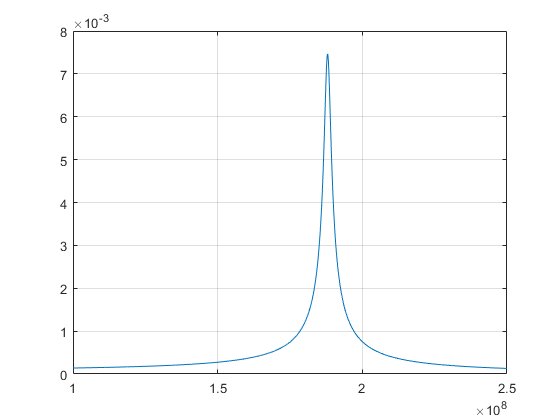

% 0.0001/((2.829e-17*f^2 - 1.0)^2 + 5.077e-21*f^2)^(1/2)
% fplot(VC01,[100e6 250e6])
x=(100:0.1:250)*1e6;
y=VC01(x);
plot(x,y)
grid on


% c)
f2=194e6 % Hz

f2 = 194000000

VC0c=VC01(f2)

$$VC0c = 0.001508$$

% 0.001508 V = 1.5 mV
VC0a/VC0c

$$ans = 4.95$$

% 4.95 - adjacent channel suppression factor